# Unidad 6 - TP08b

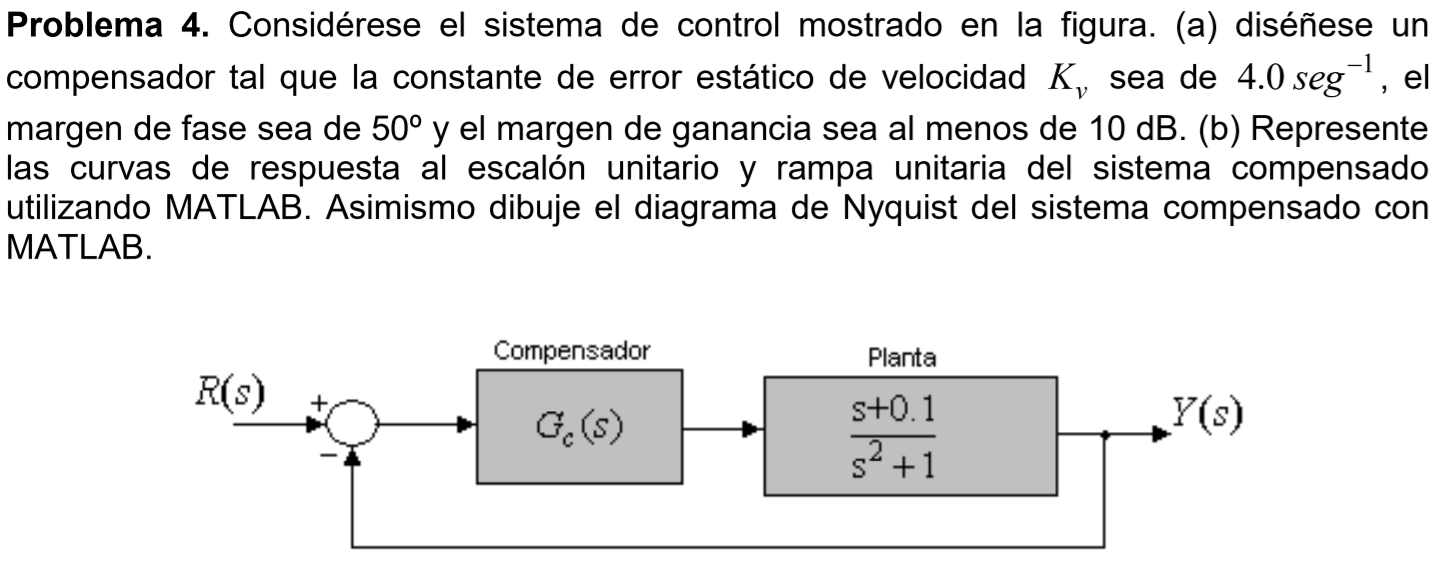

## Requisitos

- MF = 50°

- MG > 10dB

- 
$$K_V =4\;s^{-1}$$


## Analizamos la planta

Antes de comenzar a pensar nada, podemos observar que se nos requiere seguimiento finito a la rampa, por lo que vamos a tener que elevar el tipo de nuestro sistema, ya que no contamos con polo en el origen en la planta a lazo abierto, es decir nuestro sistema es *"tipo 0"*.

Al contar con un cero en nuestra planta, una buena, y necesaria, primera aproximación sería un controlador **Proporcional Integral.**


$$G_c \left(s\right)=k_p +k_I \;s$$



$$G_c \left(s\right)=\frac{k_P \;s+k_I }{s}$$



$$G_c \left(s\right)=k_p \;\frac{\left(s+\frac{k_I }{k_P }\right)}{s}$$


$G_c \left(s\right)=k_p \;\frac{\left(s+z\right)}{s}$; $z=\frac{k_I }{k_P }$

## Diseño

Al igual que en el diseño con compensadores, comenzamos con el error al permanente,


$$k_V =\underset{s\to 0}{\mathrm{lim}} \;s\;\left(k_p \right)\frac{s+z}{s}\;\frac{\left(s+0\ldotp 1\right)}{\left(s^2 +1\right)}$$



$$k_v =k_p \;z\;\left(0\ldotp 1\right)$$


De nuestro sistema inicial observamos la frecuencia del cruce por 0dB y que MF tenemos

s = tf('s');
G = (s+0.1)/(s^2+1);
H = 1;
margin(G*H);
grid on;

Observamos que ya poseemos buen MF por lo que podemos colocar nuestro cero del controlador relativamente cerca del cruce original ya que no es necesario compensar mucho

z = 2;
kv = 4;
kp = kv/(z*0.1)

Por lo tanto de la expresión de nuestro cero obtenemos $k_I$, sabiendo que $z=\frac{k_I }{k_P }$,

ki = z*kp

Quedando finalmente,


$$G_c \left(s\right)=20\;\frac{\left(s+2\right)}{s}$$


## Verificación

Gc = kp*(s+z)/s;
M = feedback(G,H)
Mc = feedback(Gc*G, H)

% Bode del compensador
bode(Gc);
grid on;

% Margenes de fase y ganancia.
bode(G*H, Gc*G*H);
grid on;
legend("Sin compensar", "Compensado");

% Respuesta al escalón
step(M, Mc);
grid on;
legend("Sin compensar", "Compensado");

% Respuesta a la rampa
[y,t]=step(M*tf(1,[1 0]), 10);
[yc,tc]=step(Mc*tf(1,[1 0]), 10);
plot(t,t,'k', t,y,'r', tc,yc,'b');
legend("Rampa unitaria", "Sin compensar", "Compensado");
grid on;

% Diagrama de Nyquist
nyquist(Gc*G);
axis([-5 5 -5 5]);
grid on;